# **Petrografía semiautomatizada de carbones.**

### **Código y ejecución.**

**Autores:** Julián David Parra, Camila Martínez.

**1. **Lectura de carpeta y creación de "cell array".

addpath('.\FunctionsStephen\')
%Lectura de Carpetas(necesario automatizar), y creación de array de celdas
Carp='.\Duplicado Imagenes Carbon02';
CarpFotos=dir(fullfile(Carp,'*.jpg'));
NumFotos=length(CarpFotos);
NomFotos={CarpFotos.name};
NomFotos=natsort(NomFotos);
TablaMuestra=cell((NumFotos/2)+1);

**2. **Bucle "for" para lectura de imágenes, creación y aplicación de máscara.

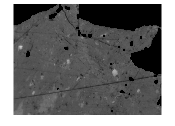

%Comando For para la creación de la máscara, y la matriz de niveles de
%grises
for c=1:NumFotos
    if (-1)^c==-1
   
    %lectura fotos pares e impares%
    
    im=imread(fullfile(Carp,NomFotos{c}));
    imS=imread(fullfile(Carp,NomFotos{c+1}));
    
    %Creación del filtro a partir de niveles de gris=70 y bordes
    imSGray=rgb2gray(imS);
    imSBW=imSGray>70;
    imSBW=bwareafilt(imSBW,[50000 inf]);
    Edge=edge(imSBW,'sobel');
    se0=strel('line',20,0);
    se90=strel('line',20,90);
    Edge=imdilate(Edge,[se90 se0]);
    imSBW(Edge==1)=0;
    
    %Aplicación del filtro a la imagen llamada sin saturacion
    imGray=rgb2gray(im);
    im=double(imGray);
    imSBW=double(imSBW);
    im=imSBW.*im;
    
    %Creación de la foto con el filtro y su adición al arreglo tipo celda
    FotoConfiltro=uint8(im);
    TablaMuestra{(c+1)/2,2}=FotoConfiltro;
    imshow(FotoConfiltro)
    
    %Creación del vectores de niveles de grises, su adición a la tabla, y la
    %suma total de estos para el vector total de la muestra
    GrayLevelPhoto=reshape(im(im>0),1,[]);
    TablaMuestra{(c+1)/2,1}=GrayLevelPhoto;
    TablaMuestra{(NumFotos/2)+1,1}=[TablaMuestra{(NumFotos/2)+1,1},GrayLevelPhoto];
    end
end

**3.** Creación de gráfico de frecuencias.

%Creación de histograma absoluto y acumulado
GrayLevelSample=TablaMuestra{(NumFotos/2)+1,1};
FrecNormal=length(GrayLevelSample(GrayLevelSample==1));
FrecAcumul=length(GrayLevelSample(GrayLevelSample==1));
DominioEnGrises=linspace(1,255,255);
for c=2:255
    %Grafica para la frecuencia absoluta
    FrecNormal=[FrecNormal,length(im(im==c))];
    %Gráfica para la frecuencia acumulada
    FrecAcumul=[FrecAcumul,length(im(im==c))+FrecAcumul(1,c-1)];
end

**4. **Conversión a niveles de reflectancia.

%Pasar de frecuencia acumulada a porcentaje de la muestra y de escala de
%grises a reflectancia
PorcentajeFrecAcumul=FrecAcumul/max(FrecAcumul)*100;
DominioEnRefl=(((DominioEnGrises.^2).*0.0000164)+(0.006042.*(DominioEnGrises))-(0.0002418));

%Calculo de derivadas
difY=gradient(PorcentajeFrecAcumul);
difX=gradient(DominioEnRefl);
Der1=(difY./difX);
dif2Y=gradient(difY);
dif2X=gradient(difX);
Der2=(dif2Y./dif2X);
[~,IptoInfEx]=max(Der2);
[~,IptoInfIn]=min(Der2);
DominioEnRefl(IptoInfEx);
DominioEnRefl(IptoInfIn);
NumeroParaExinita=round(IptoInfEx-(IptoInfEx/3));
NumeroParaInertinita=round(IptoInfIn);


**5.** Cálculo de 3 funciones lineales (para los tres grupos macerales).

%Cálculo de las 3 funciones lineales
%Función Vitrinita
[~,IndiceRo]=max(FrecNormal);
FunVi=polyfit(DominioEnRefl(1,IndiceRo-1:IndiceRo+1),PorcentajeFrecAcumul(1,IndiceRo-1:IndiceRo+1),1);

%Función Inertinita
[~,IndiceLimSupIn]=max(PorcentajeFrecAcumul);
FunIn=polyfit(DominioEnRefl(1,NumeroParaInertinita:IndiceLimSupIn),PorcentajeFrecAcumul(1,NumeroParaInertinita:IndiceLimSupIn),1);

%Función Exinita
ReflEnCeros=PorcentajeFrecAcumul(PorcentajeFrecAcumul==0);
NumReflEnCeros=length(ReflEnCeros);
IndiceLimInfEx=NumReflEnCeros+1;
FunEx=polyfit(DominioEnRefl(1,IndiceLimInfEx:NumeroParaExinita),PorcentajeFrecAcumul(1,IndiceLimInfEx:NumeroParaExinita),1);

%Cálculo de las líneas para las funciones dadas
yVi=polyval(FunVi,DominioEnRefl);
yIn=polyval(FunIn,DominioEnRefl);
yEx=polyval(FunEx,DominioEnRefl);

**6. **Creación de gráfica de frecuencia acumulada vs. reflectancia.

%Creación de la Gráfica
hold on
plot(DominioEnRefl,PorcentajeFrecAcumul)
plot(DominioEnRefl,yVi)
plot(DominioEnRefl,yIn)
plot(DominioEnRefl,yEx)
xlim([DominioEnRefl(IndiceLimInfEx+20) DominioEnRefl(IndiceLimSupIn)])
ylim([-20 120])
xlabel('Reflectancia (%)')
ylabel('Frecuencias acumuladas (%)')
annotation('textarrow',[0.3762 0.3094],[0.2937 0.1749],'String','F. acumulada (%)= 7.261')
annotation('textarrow',[0.4381 0.4109],[0.7525 0.8086],'String','F. Acumulada (%)=97.18')
hold off

title('Reflectograma Frecuencia Acumulada')

xlim([0.162 1.443])
ylim([-2 113])

%Calculo de porcentajes acumulados 
%Porcentaje acumulado de Vitrinita
[~,IndiceVi_In]=min(abs(yVi-yIn));
PorcAcumVi=yVi(IndiceVi_In);
%Porcentaje acumulado de Exinita
[~,IndiceEx_Vi]=min(abs(yVi-yEx));
if yEx(IndiceEx_Vi)>0
    PorcAcumEx=yEx(IndiceEx_Vi);
else
    PorcAcumEx=yVi(IndiceEx_Vi)
end


%Cálculo de porcentajes de cada grupo maceral y el límite en nivel de gris
%para cada grupo maceral
Porcentaje_Inertinita=100-PorcAcumVi

Porcentaje_Inertinita = 8.6771

Porcentaje_Vitrinita=PorcAcumVi-PorcAcumEx

Porcentaje_Vitrinita = 89.2698

Porcentaje_Exinita=PorcAcumEx

Porcentaje_Exinita = 2.0531

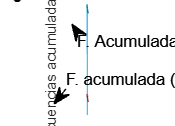

limiteExinita=IndiceEx_Vi;
limiteInertinita=IndiceVi_In;

hold on
plot(DominioEnRefl,PorcentajeFrecAcumul)
plot(DominioEnRefl,yVi)
plot(DominioEnRefl,yIn)
plot(DominioEnRefl,yEx)
xlim([DominioEnRefl(IndiceLimInfEx+20) DominioEnRefl(IndiceLimSupIn)])
ylim([-20 120])
xlabel('Reflectancia (%)')
ylabel('Frecuencias acumuladas (%)')
annotation('textarrow',[0.3762 0.3094],[0.2937 0.1749],'String','F. acumulada (%)= 7.261')
annotation('textarrow',[0.4381 0.4109],[0.7525 0.8086],'String','F. Acumulada (%)=97.18')
hold off

title('Reflectograma Frecuencia Acumulada')

xlim([0.162 1.443])
ylim([-2 113])

Porcentaje_Exinita

Porcentaje_Exinita = 2.0531

Porcentaje_Vitrinita

Porcentaje_Vitrinita = 89.2698

Porcentaje_Inertinita

Porcentaje_Inertinita = 8.6771